# 加密算法

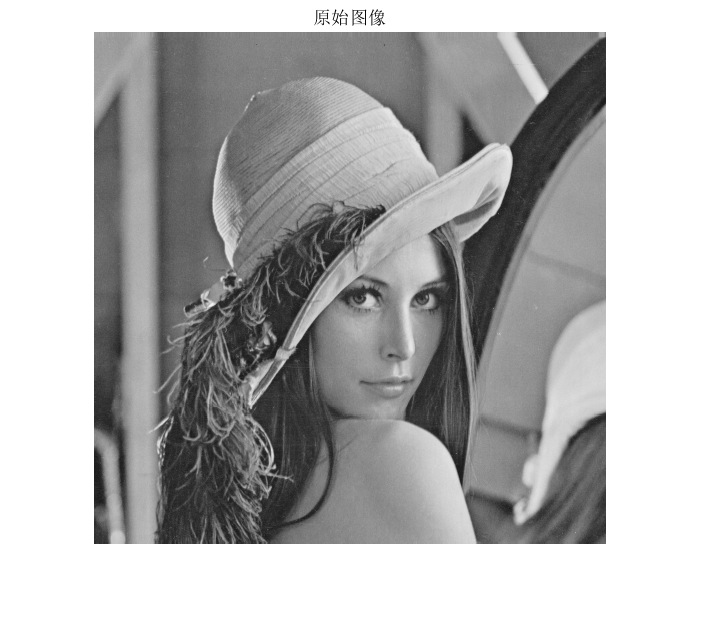

close all;
clear; clc;
% Lena图: 512x512 灰度图
I = imread('in/lena.bmp');
imshow(I); title('原始图像');

% 密钥
key = 'qwertyuiopasdfghjklzxcvbnm123456';
I1 = encrypt(I, key);

初始值x0=0.770508
参数u=3.990000


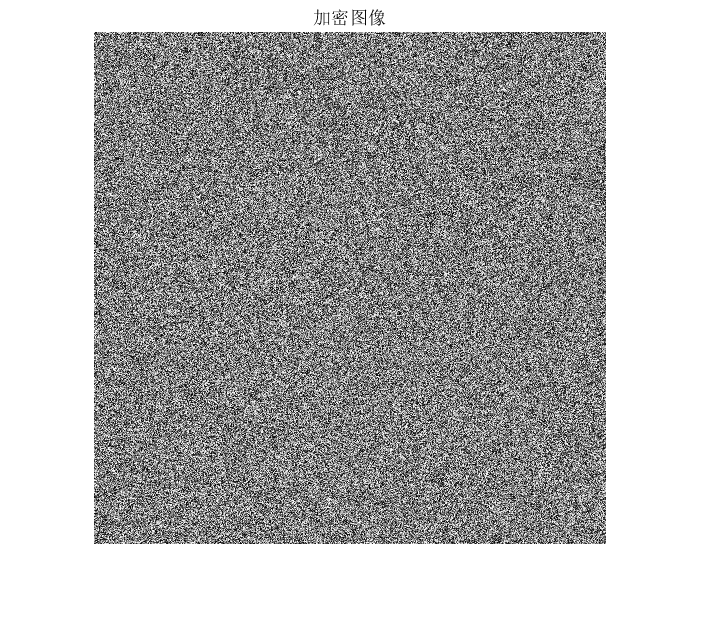

imshow(I1); title('加密图像');

I2 = decrypt(I1, key);

初始值x0=0.770508
参数u=3.990000


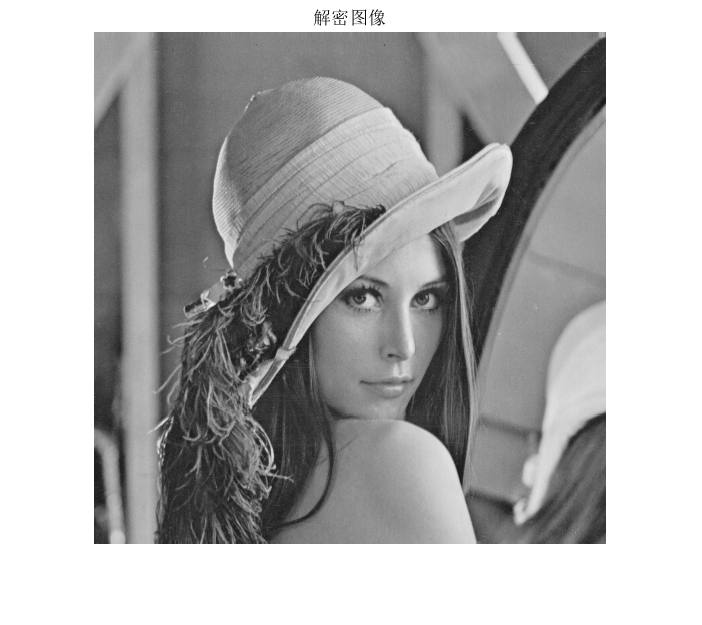

imshow(I2); title('解密图像')

function result = encrypt(img, key)
    if length(size(img)) ~= 2
        error('图像格式错误');
    end
    key_array = uint8(key);
    if length(key_array) ~= 32
        error('密钥格式错误');
    end
    s = sum(key_array);
    x0 = s / (128 * length(key_array));
    u = 3.99;
    fprintf('初始值x0=%f\n', x0);
    fprintf('参数u=%f\n', u);
    [h, w] = size(img);
    c = zeros(1, h * w);
    c(1) = x0;
    for i = 2:h*w
        c(i) = u * c(i - 1) * (1 - c(i - 1));
    end
    c1 = uint8(c * 255);
    M1 = reshape(c1, h, w);
    result1 = bitxor(img, M1);
    s = RandStream('mt19937ar', 'Seed', x0, 'NormalTransform', 'Polar');
    c2 = randperm(s, h * w);
    c3 = zeros(1, h * w);
    for i = 1:h * w
        if c3(i) == 1
            continue;
        end
        if c3(c2(i)) == 1
            continue;
        end
        temp = result1(i);
        result1(i) = result1(c2(i));
        result1(c2(i)) = temp;
        c3(i) = 1;
        c3(c2(i)) = 1;
    end
    result = result1;
end

function result = decrypt(img, key)
    if length(size(img)) ~= 2
        error('图像格式错误');
    end
    key_array = uint8(key);
    if length(key_array) ~= 32
        error('密钥格式错误');
    end
    s = sum(key_array);
    x0 = s / (128 * length(key_array));
    u = 3.99;
    fprintf('初始值x0=%f\n', x0);
    fprintf('参数u=%f\n', u);
    [h, w] = size(img);
    c = zeros(1, h * w);
    c(1) = x0;
    for i = 2:h*w
        c(i) = u * c(i - 1) * (1 - c(i - 1));
    end
    c1 = uint8(c * 255);
    M1 = reshape(c1, h, w);
    result1 = img;
    s = RandStream('mt19937ar', 'Seed', x0, 'NormalTransform', 'Polar');
    c2 = randperm(s, h * w);
    c3 = zeros(1, h * w);
    for i = 1:h * w
        if c3(i) == 1
            continue;
        end
        if c3(c2(i)) == 1
            continue;
        end
        temp = result1(i);
        result1(i) = result1(c2(i));
        result1(c2(i)) = temp;
        c3(i) = 1;
        c3(c2(i)) = 1;
    end
    result = bitxor(result1, M1);
end